# trying (and failing) to reproduce the U shaped score distribution of Yun+2019

## loading the data

global illUnits
global DEFAULT_MATFILE_DIR


load([DEFAULT_MATFILE_DIR '/cosmic_jellyfish_objectTable.mat'])
objectCJF=objectTable;
load([DEFAULT_MATFILE_DIR '/jf_galProperties_CJF.mat']);

load([DEFAULT_MATFILE_DIR '/yun19_jellyfish_objectTable.mat'])
object100=objectTable;

## Plot Yun+2019 for refernece

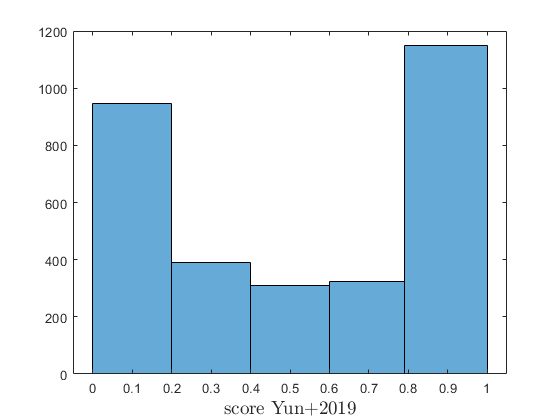

be=[0 0.2 0.4 0.6 0.79 1];
score100=double(object100.score)./5;

figure
histogram(score100,be)
xlabelmine('score Yun+2019');

## plot total CJF score distribution

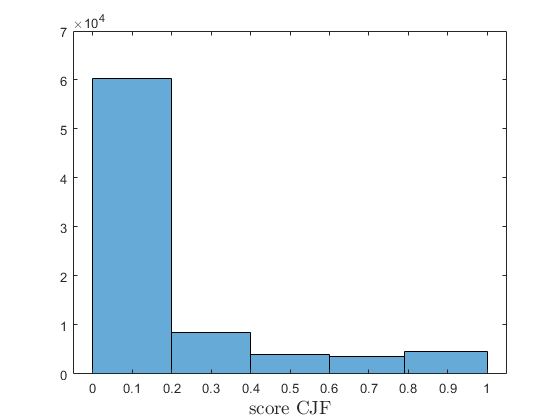


scoreCJF=double(objectCJF.score)./20;

figure
histogram(scoreCJF,be)
xlabelmine('score CJF');

## restrict CJF sample by Yun+2019 criteria

Yun+2019 criteria:

stellar mass above 9.5 (log)

host mass above 13  (log)

within 1 Rvir

gas fraction within Rgal > 1%

snaps: 63 72 84 99

% prepare masks for criteria 
hostMask=log10(galProps.hostM200c)>=13;
galMask=log10(galProps.stellarMass)>=9.5;
rpMask=galProps.rpos<=galProps.hostR200c;
fgMask=(galProps.galGasMass./galProps.stellarMass)>=0.01;
simMask=galProps.sim=="TNG100";
snapMask=galProps.snap==63 | galProps.snap==72 | ...
    galProps.snap==84 | galProps.snap==99; 

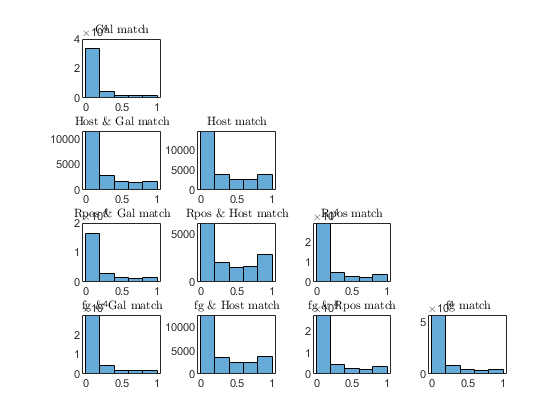

mask(1,:)=galMask;
mask(2,:)=hostMask;
mask(3,:)=rpMask;
mask(4,:)=fgMask;

tag={'Gal' 'Host' 'Rpos' 'fg'};

figure
for i=1:4
    for j=1:4
        if j>i
            continue
            
        end
        ii=4*(i-1)+j;
        subplot(4,4,ii)
        
        
        msk=mask(i,:) & mask(j,:);
        
        histogram(scoreCJF(msk),be)
        if i==j
            tagg=[tag{i}  ' match'];
        else
            tagg=[tag{i} ' \& ' tag{j} ' match'];
        end
        titlemine(tagg);
        
    end
end

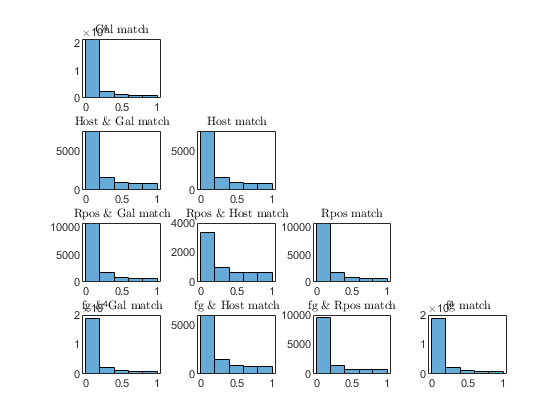


% repeat only for TNG100
mask(1,:)=galMask & simMask';
mask(2,:)=hostMask & simMask';
mask(3,:)=rpMask & simMask';
mask(4,:)=fgMask & simMask';

tag={'Gal' 'Host' 'Rpos' 'fg'};

figure
for i=1:4
    for j=1:4
        if j>i
            continue
            
        end
        ii=4*(i-1)+j;
        subplot(4,4,ii)
        
        
        msk=mask(i,:) & mask(j,:);
        
        histogram(scoreCJF(msk),be)
        if i==j
            tagg=[tag{i}  ' match'];
        else
            tagg=[tag{i} ' \& ' tag{j} ' match'];
        end
        titlemine(tagg);
        
    end
end

## more than 2 matches

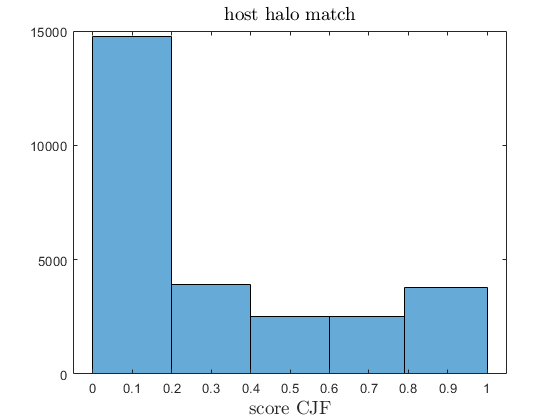


figure
histogram(scoreCJF(hostMask),be)
xlabelmine('score CJF');


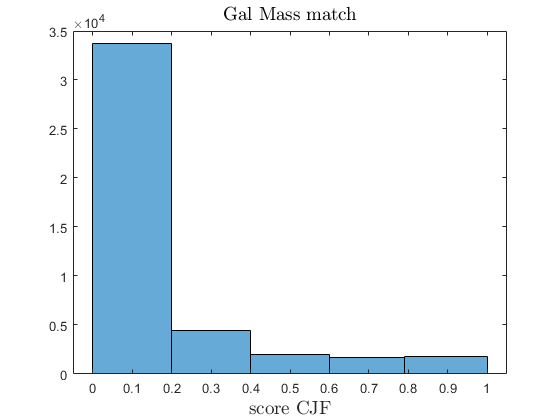


figure
histogram(scoreCJF(galMask),be)
xlabelmine('score CJF');
titlemine('Gal Mass match');

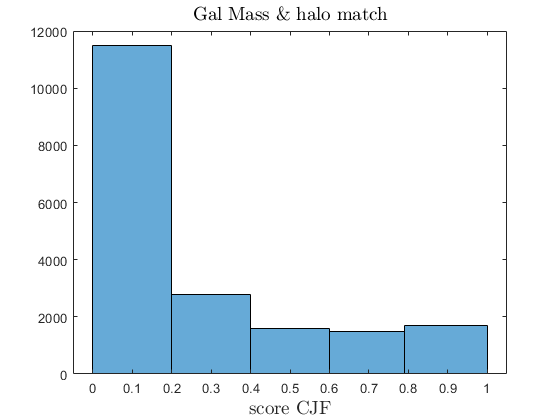


figure
histogram(scoreCJF(galMask & hostMask),be)
xlabelmine('score CJF');
titlemine('Gal Mass \&  halo match');